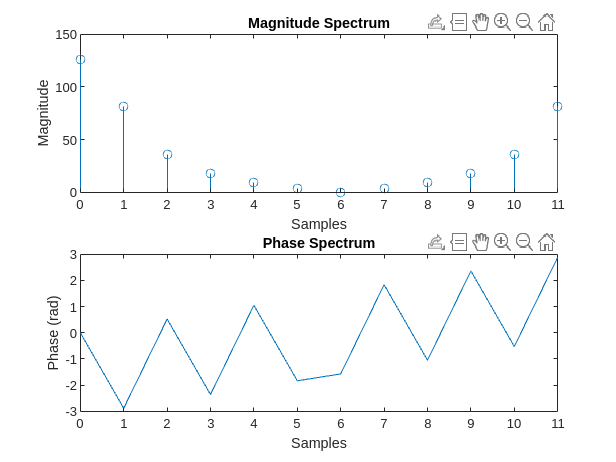

%part a
% Input signal
x = [1, 2, 4, 8, 16, 32, 32, 16, 8, 4, 2, 1];
N = 0:11;
Y = customDFT(x,N);
mag = abs(Y);
phi = angle(Y);
figure;
subplot(2,1,1);
stem(N, mag);
xlim([0 11]);xlabel('Samples');ylabel('Magnitude');title('Magnitude Spectrum');
subplot(2,1,2);
plot(N, phi);
xlim([0 11]);xlabel('Samples');ylabel('Phase (rad)');title('Phase Spectrum');

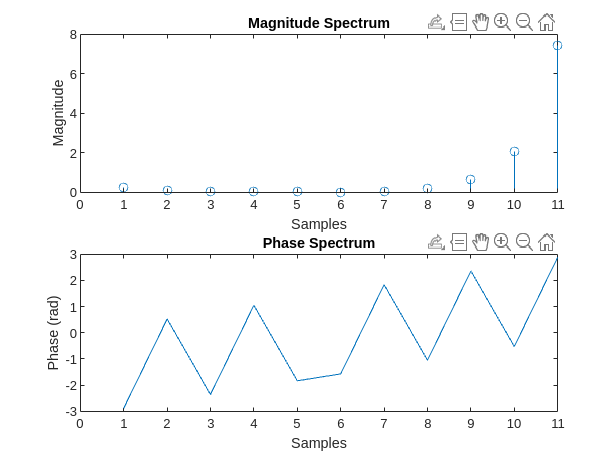


w = linspace(0, 2*pi, 12); % Adjust the range as needed
k = 0:length(N)-1;
n = 0:length(N)-1;

Aw = (1./N).*sum(exp(w-(2.*pi.*k./N)),1); %A(w) Equation
Xdtft = sum((Y.*Aw),1); %X(ejw) equation
mag = abs(Xdtft);
phi = angle(Xdtft);
figure;
subplot(2,1,1);
stem(N, mag);
xlim([0 11]);xlabel('Samples');ylabel('Magnitude');title('Magnitude Spectrum');
subplot(2,1,2);
plot(N, phi);
xlim([0 11]);xlabel('Samples');ylabel('Phase (rad)');title('Phase Spectrum');

function X = customDFT(x,N)
%To compute the DFT of the sequence x(n)
    %Checking for the length of the DFT
    N = length(N);
    Xdft = zeros(1,N); % Initialize DFT coefficients
    for k = 1:N
        for n = 1:N
            Xdft(k) = Xdft(k) + x(n)*exp(-1i*2*pi*(k-1)*(n-1)/N);
        end
    end
    X = Xdft;
end

function Xdtft = DTFT(y,N) %where y are the DFT coefficients
w = linspace(0, 2*pi, length(N)); % Adjust the range as needed
k = 0:length(N)-1;
Aw = (1./N).*sum(exp(w-(2.*pi.*k./N)),1); %A(w) Equation
Xdtft = sum((y.*Aw),1); %X(ejw) equation
end